# Compund pendulum

Physics lab 1 exam

% cleaning
clc
clear

% importing data
df1=readtable("..\data\new-exp-data-1.csv")

df1 = 14×2 table
    configuration    distance_cm
    _____________    ___________

          1              60     
          2              65     
          3              70     
          4              72     
          5              75     
          6              77     
          7              80     
          8              82     
          9              85     
         10              87     
         11              90     
         12              92     
         13              95     
         14              97     


df2=readtable("..\data\new-exp-data-2.csv")

df2 = 1462×3 table
    configuration    event    time_ms
    _____________    _____    _______

          1            1       1019  
          1            2       1018  
          1            3        998  
          1            4        999  
          1            5       1019  
          1            6       1024  
          1            7        997  
          1            8        998  
          1            9       1019  
          1           10       1016  
          1           11       1000  
          1           12        998  
          1           13       1020  
          1           14       1017  
          1           15       1016  
          1           16        995  


tools=readtable("..\data\tools.csv")

tools = 2×3 table
                tool                uncertainty      uom  
    ____________________________    ___________    _______

    {'Proximity sensor TMD4906'}       0.05        {'SEC'}
    {'Graduated rod'           }       0.01        {'MTR'}


% count configurations
uc=unique(df1.configuration); % unique configuration
nc=length(uc);                % number of configs

## Prima esplorazione e distribuzione delle misure indirette

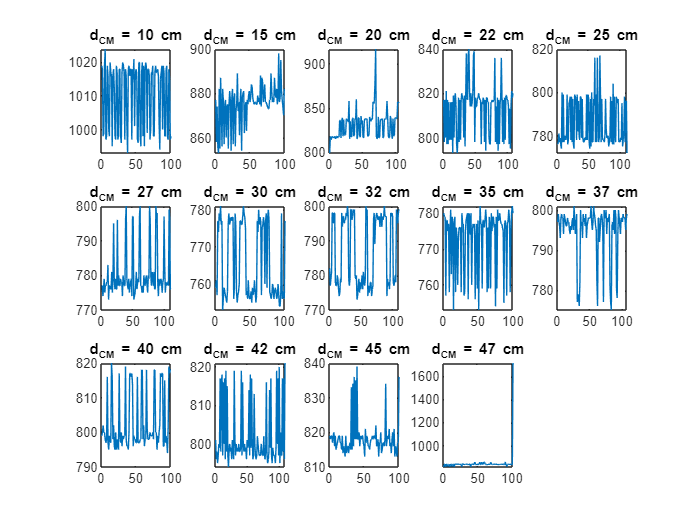

% line chart
figure
for i=1:nc
    subplot(3,5,i)
    plot(table2array(df2(df2.configuration==uc(i),"event")),table2array(df2(df2.configuration==uc(i),"time_ms")))        
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

Noto comportamento anomalo per d_cm = 47 configurazione 14. Esploro in seguito

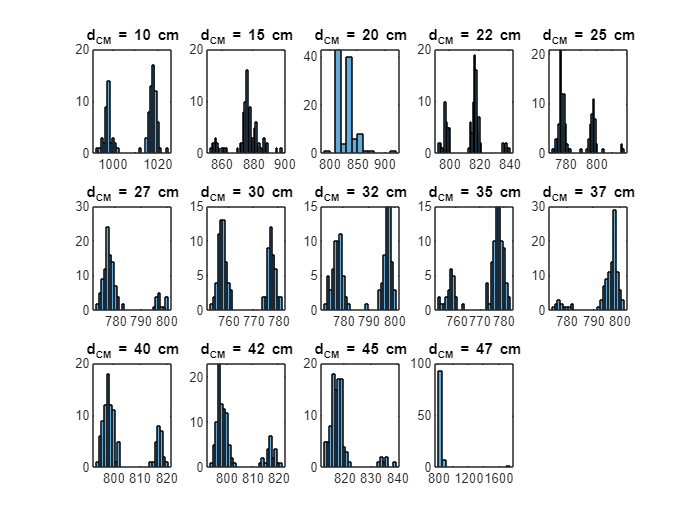

% histogram
figure
for i=1:nc
    subplot(3,5,i)
    histogram(table2array(df2(df2.configuration==uc(i),"time_ms")))     
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

## Qual è l'incertezza sui tempi?

Per stimarla, calcolo la deviazione standard sui tempi per ogni configurazione

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
dev.ratio = round((dev.deviation./dev.mean_ms).*100,2)

dev = 14×4 table
    configuration    mean_ms    deviation    ratio
    _____________    _______    _________    _____

          1           1010         10         0.99
          2            875          9         1.03
          3            831         16         1.93
          4            813         11         1.35
          5            786         11          1.4
          6            780          7          0.9
          7            766         10         1.31
          8            787         10         1.27
          9            773          9         1.16
         10            795          6         0.75
         11            803          8            1
         12            802          8            1
         13            818          5         0.61
         14            845         88        10.41


dev(height(dev),:)

ans = 1×4 table
    configuration    mean_ms    deviation    ratio
    _____________    _______    _________    _____

         14            845         88        10.41


Mi rendo conto del fatto che la configurazione 14 ha una deviazione molto più alta delle precendenti. Qualcosa non torna. Torno a valutare le misure dirette in df2 per capire se c'è qualche errore da scartare confrontandolo con la media e capendo quante deviazioni standard è fuori dalla media

% calcolo distanza dalla media in valore assoluto per ogni valore

% join con dev per ottenere tempi medi (mean_ms)
df2 = join(df2,dev,"Keys","configuration");
df2 = df2(:,["configuration","event","time_ms","mean_ms","deviation"])

df2 = 1462×5 table
    configuration    event    time_ms    mean_ms    deviation
    _____________    _____    _______    _______    _________

          1            1       1019       1010         10    
          1            2       1018       1010         10    
          1            3        998       1010         10    
          1            4        999       1010         10    
          1            5       1019       1010         10    
          1            6       1024       1010         10    
          1            7        997       1010         10    
          1            8        998       1010         10    
          1            9       1019       1010         10    
          1           10       1016       1010         10    
          1           11       1000       1010         10    
    

% compute difference in absolute value
df2.difference = abs(df2.time_ms - df2.mean_ms);

% calcola di quante deviazioni standard il valore è fuori
df2.out = round(df2.difference ./ df2.deviation,1);

% ordino il df2 per numero di deviazioni standard fuori (out decrescente)
sos = sortrows(df2,"out","descend");

% seleziono dati sospetti con out >= 3
sos(sos.out>=3,:)

ans = 16×7 table
    configuration    event    time_ms    mean_ms    deviation    difference    out
    _____________    _____    _______    _______    _________    __________    ___

         14           101      1714        845         88           869        9.9
          3            70       917        831         16            86        5.4
         13            40       839        818          5            21        4.2
         13            36       836        818          5            18        3.6
         13           100       836        818          5            18        3.6
         13            38       835        818          5            17        3.4
         10            83       775        795          6            20        3

Procedo all'eliminazione dei seguenti eventi:

- evento 101 della configurazione 14 (tempo osservato differisce dalla media di circa 10 deviazioni standard)

- evento 70 della configurazione 3 (tempo osservato differisce dalla media di più di 5 sigma)

Mi chiedo: posso rimuovere anche tutti i dati che distano più di 3 sigma? Per adesso non lo faccio

% rimuovo il dato fuori di 9 sigma
toDelete = df2.event == 101 & df2.configuration == 14;
df2(toDelete,:) = [];

% rimuovo il dato fuori di 5 sigma
toDelete = df2.event == 70 & df2.configuration == 3;
df2(toDelete,:) = [];

Alla luce dell'applicazione del criterio di Chauvenet, ricalcolo media e deviazione

% delete old mean and deviation
df2 = df2(:,["configuration", "event", "time_ms"]);

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
dev.ratio = round((dev.deviation./dev.mean_ms).*100,2)

dev = 14×4 table
    configuration    mean_ms    deviation    ratio
    _____________    _______    _________    _____

          1           1010         10        0.99 
          2            875          9        1.03 
          3            830         14        1.69 
          4            813         11        1.35 
          5            786         11         1.4 
          6            780          7         0.9 
          7            766         10        1.31 
          8            787         10        1.27 
          9            773          9        1.16 
         10            795          6        0.75 
         11            803          8           1 
         12            802          8           1 
         13            818          5        0.61 
         14            837          8        0.96 


% defining variable
l0=1;                        % pendulum length
g=9.81;                      % gravitational acceleration
dg=0.01;                     % error gravitational acceleration
dt=tools.uncertainty(1);     % error t
dr=tools.uncertainty(2);     % errror distance

% overwrite distance error
dr = 0.002; % meters

% creating empty array
tm=zeros(nc,1);     % tempi medi
dtm=zeros(nc,1);    % error t
d=zeros(nc,1);      % distance from CM
dd=zeros(nc,1);     % error distance
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(nc,1);     % gravitational acceleration calculated
dgc=zeros(nc,1);    % error gc
regc=zeros(nc,1);   % relative error gravitational acceleration
cfrg=zeros(nc,1);   % position first significant digit gravitational acceleration
uomd=string(zeros(nc,1));   % uom distance
uomg=string(zeros(nc,1));   % uom g
uomt=string(zeros(nc,1));   % uom t

% multiply *2, converting ms2s and rounding
% df2.period_s=round(df2.time_ms.*2./1000,1)
df2.period_s=df2.time_ms*2/1000

df2 = 1460×4 table
    configuration    event    time_ms    period_s
    _____________    _____    _______    ________

          1            1       1019       2.038  
          1            2       1018       2.036  
          1            3        998       1.996  
          1            4        999       1.998  
          1            5       1019       2.038  
          1            6       1024       2.048  
          1            7        997       1.994  
          1            8        998       1.996  
          1            9       1019       2.038  
          1           10       1016       2.032  
          1           11       1000           2  
          1           12        998       1.996  
          1           13       1020        2.04  
          1           14       1017       2.034  
          1           15       1016       2.

dt = 2*dt

dt = 0.1000

% core
for i=1:nc
    % calculating mean
    tm(i)=mean(table2array(df2(df2.configuration==uc(i),"period_s")));
    
    % error t
    dtm(i)=dt;
    
    % distance from CM
    d(i)=table2array(df1(df1.configuration==uc(i),"distance_cm"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %convering cm2m
    
    % error distance from CM
    dd(i)=dr;
    
    % calculating gravitational acceleration
    gc(i)=(l0.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l0.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l0.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l0.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    
    % propagation of error g
    cfrg(i)=-floor(log10(dgc(i)));  % position first significant digit g
    dgc(i)=round(dgc(i),cfrg(i));   % round dgc
    gc(i)=round(gc(i),cfrg(i)+1);   % round g calculated
    
    % relative error g
    regc(i)=round(dgc(i)./gc(i)*100,2);
    
    % unit of measure
    uomd(i)="MTR";
    uomg(i)="MSK";
    uomt(i)="SEC";
end

% significant digits time
cfrt=-floor(log10(dt));         % position first significant digit time
tm=round(tm,cfrt);              % round

% mean gravitational acceleration (output3)
gm=round(mean(gc(2:10)),1);
dgm=round(mean(dgc(2:10)),0);
regm=round((dgm/gm)*100,2);

% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

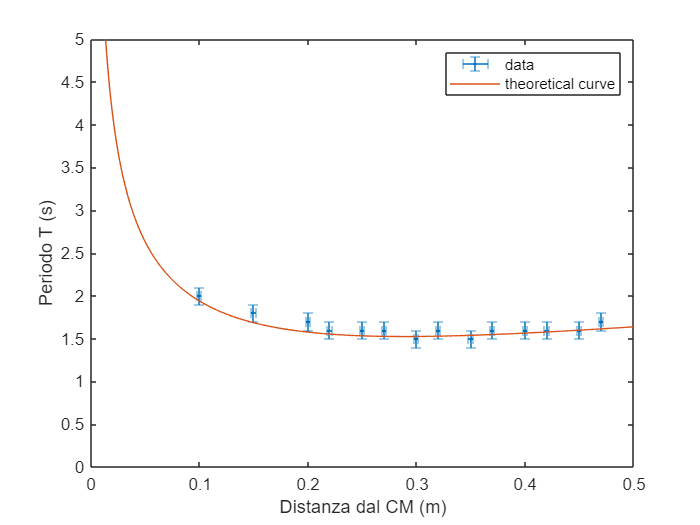

% plotting

plt=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,5])
xlim([0.0 0.5])
legend('data','theoretical curve')

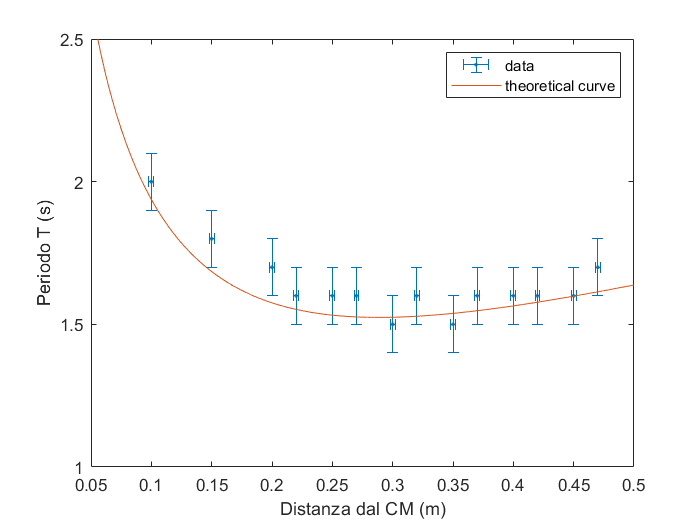


plt2=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([1 2.5])
xlim([0.05 0.5])
legend('data','theoretical curve')

% converting array to string
d=string(d);
tm=string(tm);
gc=string(gc);
regc=string(regc);

for i=1:nc
    d(i)=sprintf('%.3f',d(i));
    tm(i)=sprintf('%.2f',tm(i));
    gc(i)=sprintf('%.1f',gc(i));
    regc(i)=sprintf('%.2f',regc(i));
end

% generating output 1
output1=array2table(cat(2,string(uc),d,gc,dgc,regc,uomg),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error','uom'});
output1=sortrows(output1,"distance_CM");
output1=output1(:,{'configuration','gravitational_acceleration','uncertainty','relative_error','uom'}) %remove distance_CM

output1 = 14×5 table
    configuration    gravitational_acceleration    uncertainty    relative_error     uom 
    _____________    __________________________    ___________    ______________    _____

        "1"                    "9.0"                   "4"           "44.44"        "MSK"
        "2"                    "9.1"                   "4"           "43.96"        "MSK"
        "3"                    "8.8"                   "4"           "45.45"        "MSK"
        "4"                    "8.9"                   "4"           "44.94"        "MSK"
        "5"                    "9.3"                   "5"           "53.76"        "MSK"
        "6"                    "9.4"                   "5"           "53.19"        "MSK"
        "7"                    "9.7"                   "5"           "51.55"        "MSK


% generating output2
output2=sortrows(array2table(cat(2,string(uc),d,dd,uomd,tm,dtm,uomt),"VariableNames",{'configuration','distance_CM','uncertainty_distance','uom_distance','time','uncertainty_time','uom_time'}),"distance_CM")

output2 = 14×7 table
    configuration    distance_CM    uncertainty_distance    uom_distance     time     uncertainty_time    uom_time
    _____________    ___________    ____________________    ____________    ______    ________________    ________

        "1"            "0.100"            "0.002"              "MTR"        "2.00"         "0.1"           "SEC"  
        "2"            "0.150"            "0.002"              "MTR"        "1.80"         "0.1"           "SEC"  
        "3"            "0.200"            "0.002"              "MTR"        "1.70"         "0.1"           "SEC"  
        "4"            "0.220"            "0.002"              "MTR"        "1.60"         "0.1"           "SEC"  
        "5"            "0.250"            "0.002" 

% generating output3
output3=array2table(cat(2,gm,dgm,uomg(1),regm),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

output3 = 1×4 table
    gravitational_acceleration    uncertainty     uom     relative_error
    __________________________    ___________    _____    ______________

              "9.3"                   "5"        "MSK"       "53.76"    


% exporting csv
% writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output3,'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
% saveas(plt,'..\img\plot.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'new_livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);